# Finite Difference Method - 2D Poisson Equation

Use the FDM to solve Poisson's equation on a rectangular domain

## Step 0: preliminaries

Create and visualize a 5x7 grid using the meshgrid function

nx = 5;
Lx = 1;
dx = Lx/(nx-1); % nx-1 number of subdivisions along x
x = 0:dx:Lx;

ny = 7;
Ly = 1;
dy = Ly/(ny-1); % ny-1 number of subdivisions along y
y = 0:dy:Ly;

% so far 2 1D-grids, we need a 2D grid
% X is a matrix where each row is a copy of x, and Y is a matrix where each column is a copy of y
[X,Y] = meshgrid(x,y)

X =          0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000
         0    0.2500    0.5000    0.7500    1.0000


Y =          0         0         0         0         0
    0.1667    0.1667    0.1667    0.1667    0.1667
    0.3333    0.3333    0.3333    0.3333    0.3333
    0.5000    0.5000    0.5000    0.5000    0.5000
    0.6667    0.6667    0.6667    0.6667    0.6667
    0.8333    0.8333    0.8333    0.8333    0.8333
    1.0000    1.0000    1.0000    1.0000    1.0000


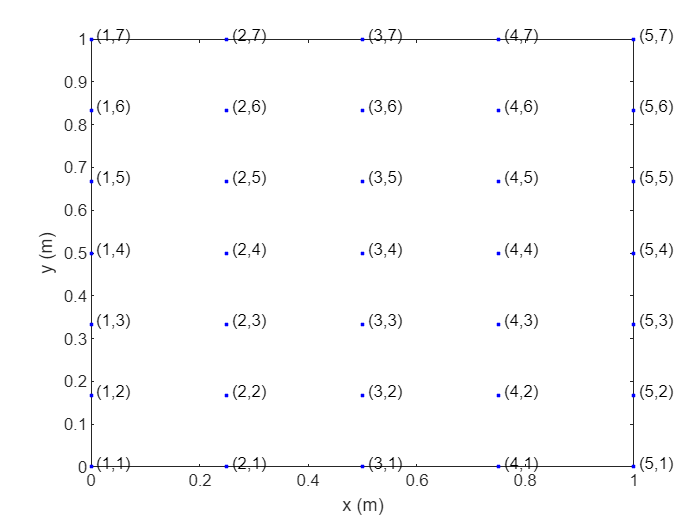


plot(X,Y,'b.');
xlabel('x (m)'); ylabel('y (m)');
hold on
for j=1:ny
    for i=1:nx
        str = strcat('(',num2str(i),',',num2str(j),')');
        text(x(i)+1E-2,y(j)+1E-2,str);
    end
end
hold off

## Step 1: Dirichlet BCs


$$    \left\{
     \begin{array}{l}
\frac{\partial^2\varphi}{\partial x^2} + \frac{\partial^2\varphi}{\partial y^2} - t(x)= 0 \\
\varphi(x,0) = \varphi_S \qquad \mathrm{South \ edge} \\
\varphi(0,y) = \varphi_W \quad \mathrm{West \ edge} \\
\varphi(L_x,y) = \varphi_E \quad \mathrm{East \ edge} \\ 
\varphi(x,L_y) = \varphi_N \quad \mathrm{North \ edge} \\
\end{array}$$


Create an m-function "FDM_2D_s1" with the following I/O scheme:

- input: geometry ($x_0$,$L_x$, $y_0$, $L_y$, number of nodes in the x and y-directions); uniform source term $t(x)=t$

- output: X,Y ("meshgridded" nodal coordinates), phi (computed values of unknown function)

Use the function to simulate a case where $n_x = 25; n_y = 25; t = -1
$ and zero Dirichlet BCs on all edges.

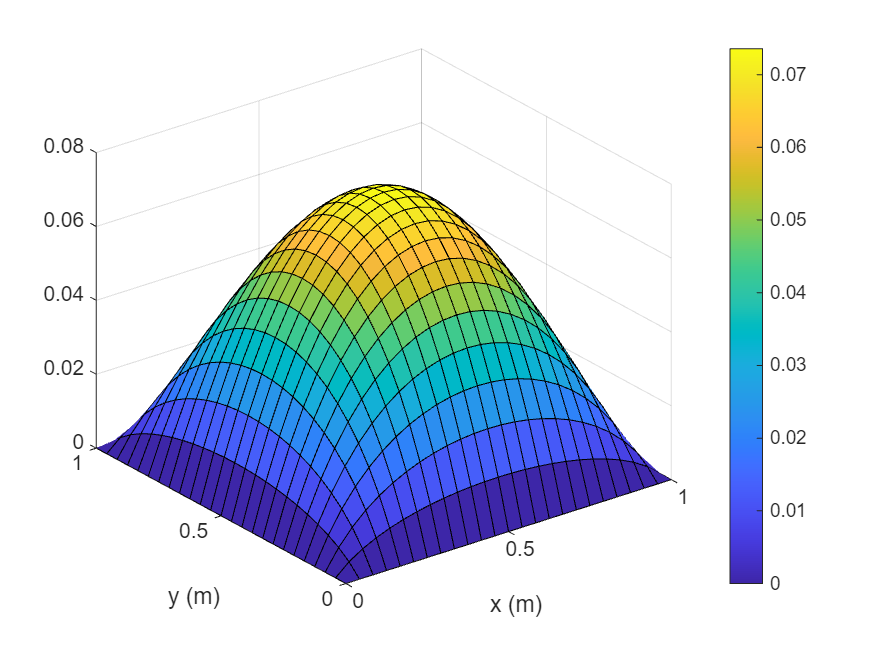

geom.nx = 25;
geom.Lx = 1;

geom.ny = 25;
geom.Ly = 1;
t = -1;

[phi,X,Y] = FDM_2D_s1(geom,t);

surf(X,Y,phi)
xlabel('x (m)')
ylabel('y (m)')
colorbar;

Compare to analytical solution obtained for a unit square domain with zero Dirichlet BCs:


$$\varphi_{\mathrm{analytical}} = \sin(\pi x) \sin(\pi y)$$


Which is obtained for


$$t(x, y) = -2\pi^2 \sin(\pi x) \sin(\pi y)$$


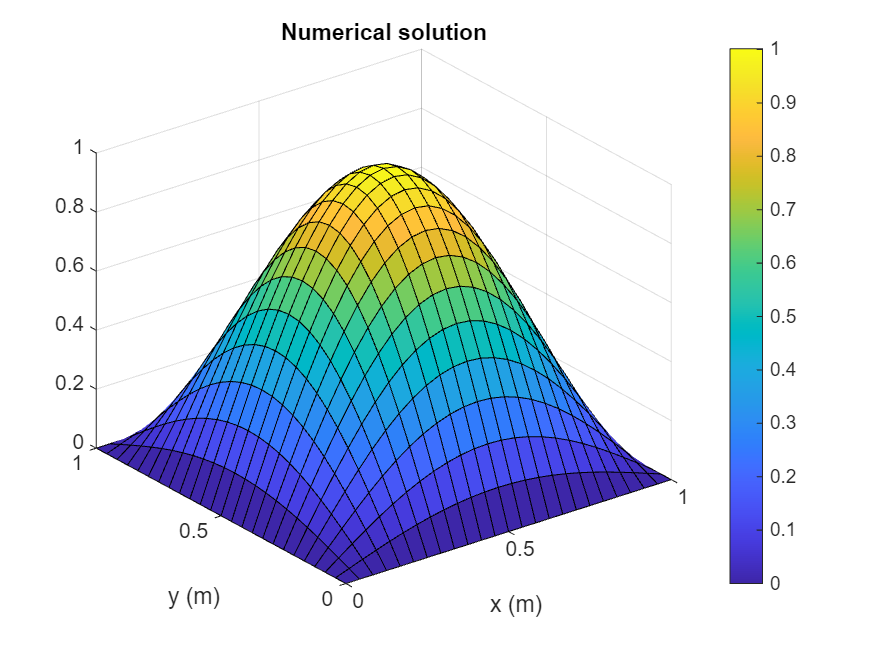

geom.nx = 25;
geom.Lx = 1;

geom.ny = 25;
geom.Ly = 1;

t = @(x,y) -2*pi^2*sin(pi*x)*sin(pi*y);

[phi,X,Y] = FDM_2D_s1(geom,t);

surf(X,Y,phi)
xlabel('x (m)')
ylabel('y (m)')
colorbar;
title('Numerical solution')

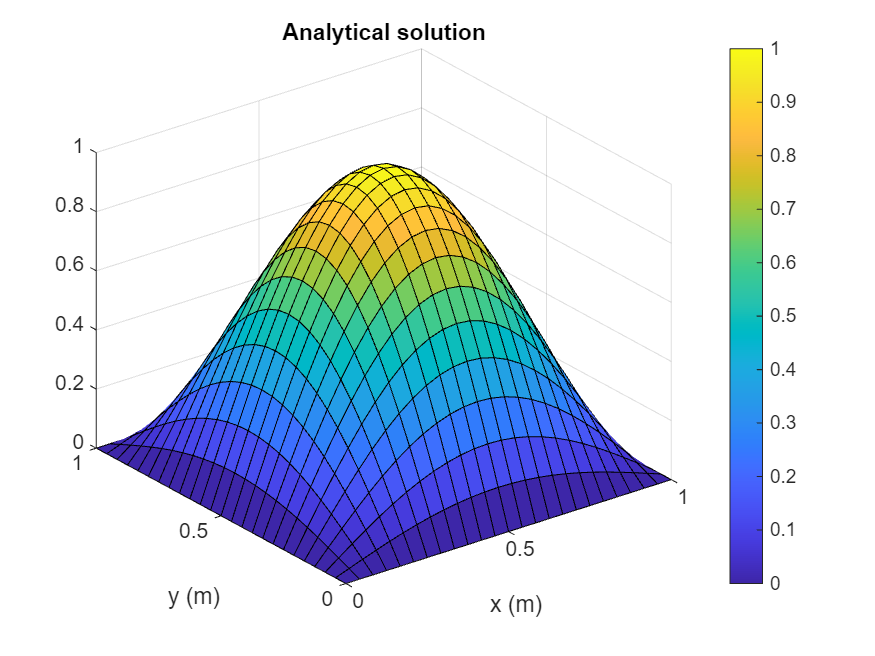

% analytical solution
phi_exact = @(x,y) sin(pi*x).*sin(pi*y);

surf(X,Y,phi_exact(X,Y))
xlabel('x (m)')
ylabel('y (m)')
colorbar;
title('Analytical solution')

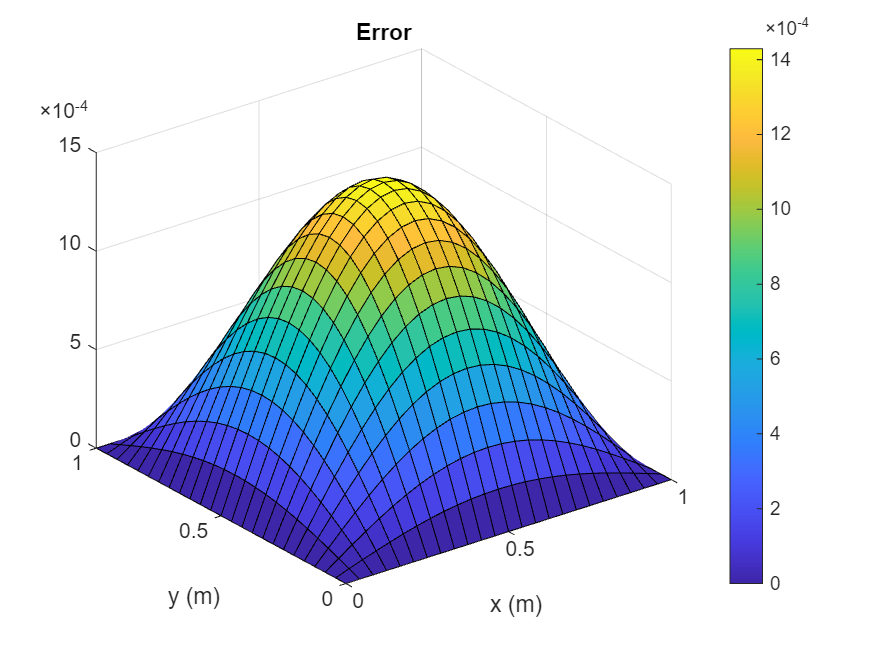

% plot of error
err = phi-phi_exact(X,Y);
surf(X,Y,err)
xlabel('x (m)')
ylabel('y (m)')
colorbar;
title('Error')

Perform a convergence test using the following grid_sizes: nx = ny = [10, 20, 40, 80].

np = [10,20,40,80]; % number of points along x and y
err = zeros(size(np));
for i = 1:length(np)
    geom.nx = np(i); % 10, 20...
    geom.ny = np(i);

    % evaluate numerical solution
    [phi,X,Y] = FDM_2D_s1(geom,t);

    % evaluate analytical solution
    exact_sol = phi_exact(X,Y);
    
    % compute the error
    err(i) = sqrt(mean((phi(:)-exact_sol(:)).^2));

    fprintf('%ix%i, err=%0.2e \n',np(i),np(i),err(i));
end

10x10, err=4.60e-03 
20x20, err=1.08e-03 
40x40, err=2.64e-04 
80x80, err=6.51e-05 


## Step 2: Dirichlet and Neumann BCs


$$    \left\{
     \begin{array}{l}
\frac{\partial^2\varphi}{\partial x^2} + \frac{\partial^2\varphi}{\partial y^2} - t(x)= 0 \\
\varphi(x,0) = \varphi_S \qquad \mathrm{South \ edge} \\
\varphi(0,y) = \varphi_W \quad \mathrm{West \ edge} \\
\frac{\partial \varphi}{\partial x}|_E = \varphi'_E \quad \mathrm{East \ edge} \\ 
\frac{\partial \varphi}{\partial y}|_N = \varphi'_N \quad \mathrm{North \ edge} \\
\end{array}$$


Create an m-function "FDM_2D_s2" and set Neumann boundary conditions on the East and North edges

Use the function to simulate a case where $n_x = 25; n_y = 25; \varphi_S = 1; \varphi_W = 0; \varphi'_N = 0; \varphi'_W = 0; t = 1
$

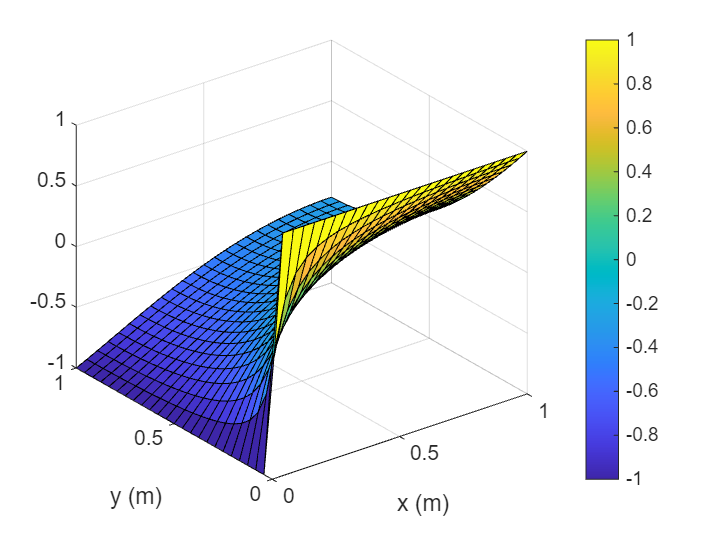

geom.nx = 25; % 4
geom.Lx = 1;

geom.ny = 25; % 4
geom.Ly = 1;
t = 1;

BCs.S.type = 'D'; % BC type on given edge
BCs.S.val = 1; % value assigned to the BC

BCs.W.type = 'D';
BCs.W.val = -1;

BCs.E.type = 'N';
BCs.E.val = 0;

BCs.N.type = 'N';
BCs.N.val = 0;

[phi,X,Y] = FDM_2D_s2(geom,BCs,t);

surf(X,Y,phi)
xlabel('x (m)')
ylabel('y (m)')
colorbar;

## Step 3: Capacitance calculation

Create an m-function "FDM_2D_s3" that allows to use a Dirichlet BC on edges N/S and Neumann on edges E/W.

Use it to compute the capacitance of a parallel-plate capacitor with $l=1 \ \mathrm{cm}$ and $d=1 \ \mathrm{mm}$, using the following relations:

Electrostatic energy stored inside the capacitor


$$W = \frac{1}{2}\int\varepsilon |E|^2dV$$


From energy, compute the capacitance


$$W = \frac{1}{2}CV^2 \rightarrow C = \frac{2 W}{V^2}$$


Check with: $C = \epsilon \frac{S}{d}$, with $S = l\cdot1$